# The Naive Bayesian Method To Check Consistency - 2 Experiments

AUTHOR: Kambadur Ananthamurthy

MAIN PROBLEM STATEMENT: Develop perspectives to understand Time Cells

NOTE: we are using the holdout method to check how good the synthetically generated datasets can

be used for Training and Decoding.

EXPERIMENT 1

--> Question: Are the methods used consistent, as far as our implementation?

Details: 333 uniquely tagged synthetic datasets were analysed on the basis

of a variety of numerical procedures. Cells in each dataset were given analog scores on the same basis.

Load the Consolidated Analysis Scores (all methods) and use these to see how well a

Naive Bayesian Decoder can predict "Time Cells".

Ground Truth: True Class Labels for the "Testing trials" (available)

EXPERIMENT 2

--> Question: Are the data used consistent, as far as our implementation?

Details: 333 uniquely tagged synthetic datasets were analysed on the basis

of a variety of numerical procedures. Cells in each dataset were given analog scores on the same basis.

Load the Synthetic Datasets, find the peaks for each of the cells, and use these to see how well

a Naive Bayesian Decoder can predict "Time Cells".

Ground Truth: True Peak frame points for the "Testing trials" (available if measured; necessary for "Training Trials")


close all
%clear

tic

input.nCells = 135;
input.nAlgos = 8;
input.nMethods = 6;

workingOnServer = 1; %Only to select the batch for datasets

if workingOnServer == 1 %Bebinca
    % Synthetic Dataset Details
    input.gDate = 20210824; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210918; %consolidation date
    input.cRun = 1; %consolidation run number
    
elseif workingOnServer == 2 %Adama
    % Synthetic Dataset Details
    input.gDate = 20210903; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210911; %consolidation date
    input.cRun = 1; %consolidation run number
end

workingOnServer = 0; %Current
diaryOn         = 0;


% Directory config

if workingOnServer == 1
    HOME_DIR = '/home/bhalla/ananthamurthy/';
    saveDirec = strcat(HOME_DIR, 'Work/Analysis/Imaging/');
elseif workingOnServer == 2
    HOME_DIR = '/home/ananth/Documents/';
    HOME_DIR2 = '/home/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
else
    HOME_DIR = '/Users/ananth/Documents/';
    HOME_DIR2 = '/Users/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
end
%Additinal search paths
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/CustomFunctions')))
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/localCopies')))
make_db

saveFolder = strcat(saveDirec, db.mouseName, '/', db.date, '/');

if diaryOn
    if workingOnServer == 1
        diary (strcat(HOME_DIR, '/logs/benchmarksDiary'))
    else
        diary (strcat(HOME_DIR2, '/logs/benchmarksDiary_', num2str(gDate), '_', num2str(gRun)))
    end
    diary on
end

% Operations
plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

% Load Synthetic Data
disp('Loading synthetic datasets ...')

Loading synthetic datasets ...


synthDataFilePath = sprintf('%s/synthDATA_%i_gRun%i_batch_%i.mat', ...
    saveFolder, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets);
load(synthDataFilePath)
disp('... done!')

... done!


% Load Analysis Results
disp('Loading analysis results ...')

Loading analysis results ...


analysisFilePath = sprintf('%s/synthDATA_Analysis_%i_cRun%i_cData.mat', ...
    saveFolder, ...
    input.cDate, ...
    input.cRun);
load(analysisFilePath)
disp('... done!')

... done!



input.removeNaNs = 0;
input.saveFolder = saveFolder;


## Experiment 1

- Feed the scores from all the methods to a Naive Bayesian Method

- Check against ground truth

%Prepare the Look Up Table (LUT)
[response, predictor] = getTheTable(sdo_batch, cData, input);

Creating Look Up Table ...
... done!



%Normalize
maxima = max(predictor);
normPredictor = predictor./maxima;

%Z-Score
zPredictor = zscore(predictor);

% Normalize Z-Score
maxima = max(zPredictor);
nzPredictor = zPredictor./maxima;

% Preprocessing
Z = predictor(:, 1:5); % One can chose any of the other normalized or standardized versions

mode = 'random'; 

% It is probably not best to just consider the first n observations (less we miss something).
% A second method could be to use k-fold crossvalidation, however this is not recommended for
% large datasets. For now, I'm using % holdout.

%holdoutPercent = 30; % in %

myRange = 30:10:90;
%myRange = [30, 50];
nConditions = length(myRange);
allErrorRates = zeros(nConditions, 1); %7 steps from 30 to 90 (stepsize 10).\
allFPRates = zeros(nConditions, 1);
allFNRates = zeros(nConditions, 1);
allConsistency = zeros(nConditions, 1);

for condition = 1:nConditions
    % Select Training and Testing Observations
    nObs = size(Z, 1);
    v = 1:nObs;
    iTestingObs = v; %preallocate; will eventually remove training observations

    
    holdoutPercent = myRange(condition); %the fraction of observations left out for testing
    
    nTrainingObs = round(((100-holdoutPercent)*nObs)/100);
    
    %luckily, MATLAB allows "clearing" of non-existent variables, if any
    clear iTrainingObs
    clear X
    clear X0
    clear Y
    clear Y0
    clear YDiff
    
    if strcmpi(mode, 'random')
        iTrainingObs = sort(randperm(nObs, nTrainingObs));
    end
    
    iTestingObs(iTrainingObs) = []; %remove training observations
    
    X = Z(iTrainingObs, :); % Data that will be used to train
    Y = response(iTrainingObs); % Labels for the corresponding training observations (Ground Truth)
    
    X0 = Z(iTestingObs, :); % Data that will be used for testing
    Y0 = response(iTestingObs); % Labels for the corresponding testing observations (Ground Truth)
    
    % Train the model
    distribution4Bayes = 'mvmn'; %options:'kernel', 'mv', 'mvmn', or 'normal'
    %clear Mdl
    Mdl = fitcnb(X, Y, ...
        'distributionnames', distribution4Bayes, ...
        'ClassNames', Y);
    
    % Test the model
    Yfit = predict(Mdl, X0);
    
    % We have to now see how different Yfit is to Y0.
    % NOTE: If we do YDiff = Y0-Yfit, for each of the values,
    % 0: correct prediction
    % -1: False Positive (FP)
    % 1: False Negative (FN)
    
    YDiff = Y0-Yfit;
    
    nWrongAnswers = length(find(YDiff)); %finds non zero elements
    errorRate = (nWrongAnswers/nObs)*100; % in %
    consistency = 100 - errorRate; %in %
    fprintf('For holdout: %i Error Rate: %0.4f, so Consistency: %0.4f\n', holdoutPercent, errorRate, consistency)
    
    allErrorRates(condition) = errorRate;
    allFPRates(condition) = length(YDiff(YDiff==-1))/nObs;
    allFNRates(condition) = length(YDiff(YDiff==1))/nObs;
    allConsistency(condition) = consistency;
end

For holdout: 30 Error Rate: 1.3569, so Consistency: 98.6431


For holdout: 40 Error Rate: 1.7818, so Consistency: 98.2182


For holdout: 50 Error Rate: 2.3112, so Consistency: 97.6888


For holdout: 60 Error Rate: 2.6627, so Consistency: 97.3373


For holdout: 70 Error Rate: 3.1854, so Consistency: 96.8146


For holdout: 80 Error Rate: 40.5784, so Consistency: 59.4216


For holdout: 90 Error Rate: 4.0952, so Consistency: 95.9048


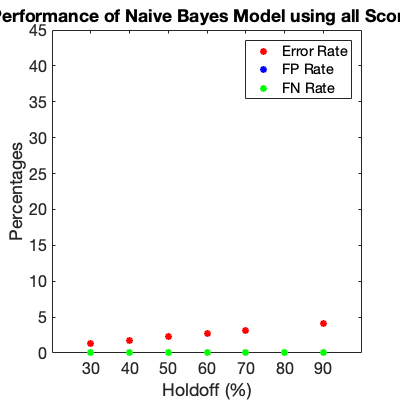

figureDetails = compileFigureDetails(16, 2, 5, 0.2, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
fig1 = figure(1);
clf
set(fig1, 'Position', [100, 100, 400, 400])
plot(allErrorRates, 'r*', ...
    'LineWidth', 2)
hold on
plot(allFPRates/nObs, 'b*', ...
    'LineWidth', 2)
hold on
plot(allFNRates/nObs, 'g*', ...
    'LineWidth', 2)
% hold on
% plot(allConsistency, 'y*', ...
%     'LineWidth', 2)
hold off
legend({'Error Rate', 'FP Rate', 'FN Rate'})
title('Performance of Naive Bayes Model using all Scores', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight','bold')
xlabel('Holdoff (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Percentages', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticklabels({'30', '40', '50', '60', '70', '80', '90'})
set(gca, 'FontSize', figureDetails.fontSize)


% print(sprintf('%s/ConsistencyTest1-%i-%i-%i-%i-%i_%i', ...
%     HOME_DIR2, ...
%     input.gDate, ...
%     input.gRun, ...
%     input.nDatasets, ...
%     input.cDate, ...
%     input.cRun, ...
%     workingOnServer), ...
%     -'dpng')

toc

Elapsed time is 2954.470279 seconds.


## Experiment 2

- Seach the data for peaks, and feed these to the Naive Bayesian Method

- Check against ground truth

tic

% Preprocessing
nDatasets = length(sdo_batch);

nCells = size(sdo_batch(1).syntheticDATA, 1);
nTrials = size(sdo_batch(1).syntheticDATA, 2);
%nFrames = size(sdo_batch(1).syntheticDATA, 3);
reality = zeros(nCells, 1); %Preallocate

count = 0;
allPeaks = zeros(nDatasets*nCells*nTrials, 1);
response2 = zeros(nDatasets*nCells*nTrials, 1);
for dataset = 1:nDatasets
    for cell = 1:nCells
        for trial = 1:nTrials
            count = count + 1;
            [~, peaki] = max(sdo_batch(dataset).syntheticDATA(cell, trial, :));
            %allPeaks = [allPeaks peaki]
            allPeaks(count) = peaki;
            if ismember(sdo_batch(dataset).ptcList, cell)           
                response2(count) = 1;
            else
                response2(count) = 0;
            end
        end
    end
end
Z = allPeaks;

mode = 'random'; 

% It is probably not best to just consider the first n observations (less we miss something).
% A second method could be to use k-fold crossvalidation, however this is not recommended for
% large datasets. For now, I'm using % holdout.

%holdoutPercent = 30; % in %

myRange = 30:10:90;

nConditions = length(myRange);
allErrorRates = zeros(nConditions, 1); %7 steps from 30 to 90 (stepsize 10).\
allFPRates = zeros(nConditions, 1);
allFNRates = zeros(nConditions, 1);
allConsistency = zeros(nConditions, 1);

for condition = 1:nConditions
    % Select Training and Testing Observations
    nObs = size(Z, 1);
    v = 1:nObs;
    iTestingObs = v; %preallocate; will eventually remove training observations

    
    holdoutPercent = myRange(condition); %the fraction of observations left out for testing
    
    nTrainingObs = round(((100-holdoutPercent)*nObs)/100);
    
    %luckily, MATLAB allows "clearing" of non-existent variables, if any
    clear iTrainingObs
    clear X
    clear X0
    clear Y
    clear Y0
    clear YDiff
    
    if strcmpi(mode, 'random')
        iTrainingObs = sort(randperm(nObs, nTrainingObs));
    end
    
    iTestingObs(iTrainingObs) = []; %remove training observations
    
    X = Z(iTrainingObs, 1); % Data that will be used to train
    Y = response2(iTrainingObs); % Labels for the corresponding training observations (Ground Truth)
    
    X0 = Z(iTestingObs, 1); % Data that will be used for testing
    Y0 = response2(iTestingObs); % Labels for the corresponding testing observations (Ground Truth)
    
    % Train the model
    distribution4Bayes = 'mvmn'; %options:'kernel', 'mv', 'mvmn', or 'normal'
    %clear Mdl
    Mdl = fitcnb(X, Y, ...
        'distributionnames', distribution4Bayes, ...
        'ClassNames', Y);
    
    % Test the model
    Yfit = predict(Mdl, X0);
    
    % We have to now see how different Yfit is to Y0.
    % NOTE: If we do YDiff = Y0-Yfit, for each of the values,
    % 0: correct prediction
    % -1: False Positive (FP)
    % 1: False Negative (FN)
    
    YDiff = Y0-Yfit;
    
    nWrongAnswers = length(find(YDiff)); %finds non zero elements
    errorRate = (nWrongAnswers/nObs)*100; % in %
    consistency = 100 - errorRate; %in %
    fprintf('For holdout: %i Error Rate: %0.4f, so Consistency: %0.4f\n', holdoutPercent, errorRate, consistency)
    
    allErrorRates(condition) = errorRate;
    allFPRates(condition) = length(YDiff(YDiff==-1))/nObs;
    allFNRates(condition) = length(YDiff(YDiff==1))/nObs;
    allConsistency(condition) = consistency;
end
figureDetails = compileFigureDetails(16, 2, 5, 0.2, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
fig2 = figure(2);
clf
set(fig1, 'Position', [100, 100, 400, 400])
plot(allErrorRates, 'r*', ...
    'LineWidth', 2)
hold on
plot(allFPRates/nObs, 'b*', ...
    'LineWidth', 2)
hold on
plot(allFNRates/nObs, 'g*', ...
    'LineWidth', 2)
% hold on
% plot(allConsistency, 'y*', ...
%     'LineWidth', 2)
hold off
legend({'Error Rate', 'FP Rate', 'FN Rate'})
title('Performance of Naive Bayes Model using all Scores', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight','bold')
xlabel('Holdoff (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Percentages', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticklabels({'30', '40', '50', '60', '70', '80', '90'})
set(gca, 'FontSize', figureDetails.fontSize)

% print(sprintf('%s/ConsistencyTest2-%i-%i-%i-%i-%i_%i', ...
%     HOME_DIR2, ...
%     input.gDate, ...
%     input.gRun, ...
%     input.nDatasets, ...
%     input.cDate, ...
%     input.cRun, ...
%     workingOnServer), ...
%     -'dpng')

toc


## Mod Experiment 2 (if actual Experiment 2 fails, first alternative)

- Seach the data for peaks, limit the data, and feed these to the Naive Bayesian Method

- Check against ground truth

tic

% Preprocessing
nDatasets = length(sdo_batch);

nCells = size(sdo_batch(1).syntheticDATA, 1);
nTrials = size(sdo_batch(1).syntheticDATA, 2);
%nFrames = size(sdo_batch(1).syntheticDATA, 3);
reality = zeros(nCells, 1); %Preallocate

count = 0;
allPeaks = zeros(nDatasets*nCells*nTrials, 1);
response2 = zeros(nDatasets*nCells*nTrials, 1);
for dataset = 1:nDatasets
    for cell = 1:nCells
        for trial = 1:nTrials
            count = count + 1;
            [~, peaki] = max(sdo_batch(dataset).syntheticDATA(cell, trial, :));
            %allPeaks = [allPeaks peaki]
            allPeaks(count) = peaki;
            if ismember(sdo_batch(dataset).ptcList, cell)           
                response2(count) = 1;
            else
                response2(count) = 0;
            end
        end
    end
end
Z = allPeaks;

%limiting condition
trueLength = length(Z);
selectObs = sort(randperm(length(Z), round(trueLength/6)));
Z = Z(selectObs);
response2 = response2(selectObs);

mode = 'random'; 

% It is probably not best to just consider the first n observations (less we miss something).
% A second method could be to use k-fold crossvalidation, however this is not recommended for
% large datasets. For now, I'm using % holdout.

%holdoutPercent = 30; % in %

myRange = 30:10:90;

nConditions = length(myRange);
allErrorRates = zeros(nConditions, 1); %7 steps from 30 to 90 (stepsize 10).\
allFPRates = zeros(nConditions, 1);
allFNRates = zeros(nConditions, 1);
allConsistency = zeros(nConditions, 1);

for condition = 1:nConditions
    % Select Training and Testing Observations
    nObs = size(Z, 1);
    v = 1:nObs;
    iTestingObs = v; %preallocate; will eventually remove training observations

    
    holdoutPercent = myRange(condition); %the fraction of observations left out for testing
    
    nTrainingObs = round(((100-holdoutPercent)*nObs)/100);
    
    %luckily, MATLAB allows "clearing" of non-existent variables, if any
    clear iTrainingObs
    clear X
    clear X0
    clear Y
    clear Y0
    clear YDiff
    
    if strcmpi(mode, 'random')
        iTrainingObs = sort(randperm(nObs, nTrainingObs));
    end
    
    iTestingObs(iTrainingObs) = []; %remove training observations
    
    X = Z(iTrainingObs, 1); % Data that will be used to train
    Y = response2(iTrainingObs); % Labels for the corresponding training observations (Ground Truth)
    
    X0 = Z(iTestingObs, 1); % Data that will be used for testing
    Y0 = response2(iTestingObs); % Labels for the corresponding testing observations (Ground Truth)
    
    % Train the model
    distribution4Bayes = 'mvmn'; %options:'kernel', 'mv', 'mvmn', or 'normal'
    %clear Mdl
    Mdl = fitcnb(X, Y, ...
        'distributionnames', distribution4Bayes, ...
        'ClassNames', Y);
    
    % Test the model
    Yfit = predict(Mdl, X0);
    
    % We have to now see how different Yfit is to Y0.
    % NOTE: If we do YDiff = Y0-Yfit, for each of the values,
    % 0: correct prediction
    % -1: False Positive (FP)
    % 1: False Negative (FN)
    
    YDiff = Y0-Yfit;
    
    nWrongAnswers = length(find(YDiff)); %finds non zero elements
    errorRate = (nWrongAnswers/nObs)*100; % in %
    consistency = 100 - errorRate; %in %
    fprintf('For holdout: %i Error Rate: %0.4f, so Consistency: %0.4f\n', holdoutPercent, errorRate, consistency)
    
    allErrorRates(condition) = errorRate;
    allFPRates(condition) = length(YDiff(YDiff==-1))/nObs;
    allFNRates(condition) = length(YDiff(YDiff==1))/nObs;
    allConsistency(condition) = consistency;
end
figureDetails = compileFigureDetails(16, 2, 5, 0.2, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
fig2 = figure(2);
clf
set(fig2, 'Position', [100, 100, 400, 400])
plot(allErrorRates, 'r*', ...
    'LineWidth', 2)
hold on
plot(allFPRates/nObs, 'b*', ...
    'LineWidth', 2)
hold on
plot(allFNRates/nObs, 'g*', ...
    'LineWidth', 2)
% hold on
% plot(allConsistency, 'y*', ...
%     'LineWidth', 2)
hold off
legend({'Error Rate', 'FP Rate', 'FN Rate'})
title('Performance of Naive Bayes Model using all Scores', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight','bold')
xlabel('Holdoff (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Percentages', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticklabels({'30', '40', '50', '60', '70', '80', '90'})
set(gca, 'FontSize', figureDetails.fontSize)

print(sprintf('%s/ConsistencyTest2-%i-%i-%i-%i-%i_%i', ...
    HOME_DIR2, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets, ...
    input.cDate, ...
    input.cRun, ...
    workingOnServer), ...
    -'dpng')

toc

## Modified Experiment 2 (if actual Experiment 2 fails; last resort)

- Seach the data for trial-averaged peak indices, and feed these to the Naive Bayesian Method

- Check against ground truth

tic

% Preprocessing
nDatasets = length(sdo_batch);

nCells = size(sdo_batch(1).syntheticDATA, 1);
nTrials = size(sdo_batch(1).syntheticDATA, 2);
%nFrames = size(sdo_batch(1).syntheticDATA, 3);
reality = zeros(nCells, 1); %Preallocate

count = 0;
allPeaks = zeros(nTrials, 1);
avgAllPeaks = zeros(nDatasets*nCells, 1);
response2 = zeros(nDatasets*nCells, 1);
for dataset = 1:nDatasets
    for cell = 1:nCells
        count = count + 1;
        for trial = 1:nTrials
            [~, peaki] = max(sdo_batch(dataset).syntheticDATA(cell, trial, :));
            %allPeaks = [allPeaks peaki]
            allPeaks(trial) = peaki;
        end
        avgAllPeaks(count) = mean(allPeaks);
        if ismember(sdo_batch(dataset).ptcList, cell)
            response2(count) = 1;
        else
            response2(count) = 0;
        end
    end
end
Z = allPeaks;

mode = 'random'; 

% It is probably not best to just consider the first n observations (less we miss something).
% A second method could be to use k-fold crossvalidation, however this is not recommended for
% large datasets. For now, I'm using % holdout.

%holdoutPercent = 30; % in %

myRange = 30:10:90;

nConditions = length(myRange);
allErrorRates = zeros(nConditions, 1); %7 steps from 30 to 90 (stepsize 10).\
allFPRates = zeros(nConditions, 1);
allFNRates = zeros(nConditions, 1);
allConsistency = zeros(nConditions, 1);

for condition = 1:nConditions
    % Select Training and Testing Observations
    nObs = size(Z, 1);
    v = 1:nObs;
    iTestingObs = v; %preallocate; will eventually remove training observations

    
    holdoutPercent = myRange(condition); %the fraction of observations left out for testing
    
    nTrainingObs = round(((100-holdoutPercent)*nObs)/100);
    
    %luckily, MATLAB allows "clearing" of non-existent variables, if any
    clear iTrainingObs
    clear X
    clear X0
    clear Y
    clear Y0
    clear YDiff
    
    if strcmpi(mode, 'random')
        iTrainingObs = sort(randperm(nObs, nTrainingObs));
    end
    
    iTestingObs(iTrainingObs) = []; %remove training observations
    
    X = Z(iTrainingObs, 1); % Data that will be used to train
    Y = response2(iTrainingObs); % Labels for the corresponding training observations (Ground Truth)
    
    X0 = Z(iTestingObs, 1); % Data that will be used for testing
    Y0 = response2(iTestingObs); % Labels for the corresponding testing observations (Ground Truth)
    
    % Train the model
    distribution4Bayes = 'mvmn'; %options:'kernel', 'mv', 'mvmn', or 'normal'
    %clear Mdl
    Mdl = fitcnb(X, Y, ...
        'distributionnames', distribution4Bayes, ...
        'ClassNames', Y);
    
    % Test the model
    Yfit = predict(Mdl, X0);
    
    % We have to now see how different Yfit is to Y0.
    % NOTE: If we do YDiff = Y0-Yfit, for each of the values,
    % 0: correct prediction
    % -1: False Positive (FP)
    % 1: False Negative (FN)
    
    YDiff = Y0-Yfit;
    
    nWrongAnswers = length(find(YDiff)); %finds non zero elements
    errorRate = (nWrongAnswers/nObs)*100; % in %
    consistency = 100 - errorRate; %in %
    fprintf('For holdout: %i Error Rate: %0.4f, so Consistency: %0.4f\n', holdoutPercent, errorRate, consistency)
    
    allErrorRates(condition) = errorRate;
    allFPRates(condition) = length(YDiff(YDiff==-1))/nObs;
    allFNRates(condition) = length(YDiff(YDiff==1))/nObs;
    allConsistency(condition) = consistency;
end
figureDetails = compileFigureDetails(16, 2, 5, 0.2, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
fig2 = figure(2);
clf
set(fig2, 'Position', [100, 100, 400, 400])
plot(allFPRates/nObs, 'b*', ...
    'LineWidth', 2)
hold on
plot(allFNRates/nObs, 'g*', ...
    'LineWidth', 2)
plot(allErrorRates, 'r*', ...
    'LineWidth', 2)
% hold on
% plot(allConsistency, 'y*', ...
%     'LineWidth', 2)
hold off
legend({'FP Rate', 'FN Rate', 'Error Rate'})
title('Performance of Naive Bayes Model using all Peaks', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight','bold')
xlabel('Holdout (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Percentages', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticklabels({'30', '40', '50', '60', '70', '80', '90'})
set(gca, 'FontSize', figureDetails.fontSize)

% print(sprintf('%s/ConsistencyTest2-%i-%i-%i-%i-%i_%i', ...
%     HOME_DIR2, ...
%     input.gDate, ...
%     input.gRun, ...
%     input.nDatasets, ...
%     input.cDate, ...
%     input.cRun, ...
%     workingOnServer), ...
%     -'dpng')

toc